# Heat Exchanger behaviour

This livescript is a brief manual in support of the app ***HeatExchanger.mlapp***.  This is a simple heat exchanger with inlet flow rate F, inlet temperature Tin, outlet temperature T and mass flow rate of steam Q. The aim is to model how the outlet temperature depends upon the inlet temperature and the supplied heating, the flow rate and the tank volume. These notes give the engineering and analytical background alongside some simple MATLAB code snippets than can be used for equivalent analysis.

A logical next file (in development) is ***HeatExchanger_with_PI***  which looks at how to control the temperature using a PI compensator.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by P. Soulatiantork  and  J.A. Rossiter, University of Sheffield                      

                         

## Table of contents

- Context of the heat exchanger system

- Open-loop step response analysis

- Using the app to validate expectations

- Supporting MATLAB code

-  Interface and user interaction of the app file

## 1. Context of the Heat Exchanger system 

The heat exchanger used in this app has cold water entering with temperature ***Tin*** and hotter water exciting with temperature ***T***. It is assumed that the tank is well mixed so that the temperature throughout the tank is also ***T***. Heating is provided by condensing steam, and thus the latent heat released is dependent on the mass flow rate of that steam. The picture below gives a representation of that scenario. The app deploys the following assumptions:

- The Volume of the tank, the inlet flow rate, inlet temperature and mass flow rate of the steam can be modified by the user. 

- For simplicity here we assume that the flow in (*F*) and the flow out are equal. This means the volume *V* of water in the tank is fixed. The size of  the tank in the app is varied to represent changes in volume.

- Assume the tank is well mixed so the temperature T throughout is equal and matches the outlet temperature. The colour in the tank represents temperature (dark blue for cold and red/pink for hot).

- The specific heat $C_p$ and density ρ of the liquid are known (here taken to be water).

- The heat supply can be approximated closely enough by just the latent heat λ of the steam. The thickeness of  the red line represents the steam mass flow rate.

- For convenience, we assume that the initial temperature in the tank is ************************.

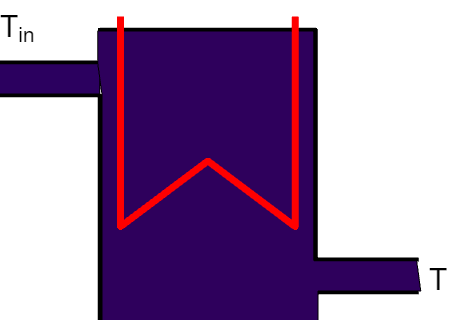

There are two inputs to the system:

- Inlet temperature Tin 

- Mass flow rate of steam Q 

### Model of the heat exchanger uses Energy/Power balance

A typical balance equation to use for modelling thermal systems is as follows:

            Accumulation of Energy = Energy in – Energy out

In practice we do this as a power balance, that is energy per second.

- The rate of energy coming into the tank is determined by inlet mass flow rate $\rho F$ and inlet temperature. Energy flow rate in = $\rho {\textrm{FC}}_p T_{\textrm{in}} \;$. 

- The rate of energy coming out of the tank is determined by outlet mass flow rate $\rho F$ and outlet temperature. Energy flow rate out = $\rho {\mathrm{FC}}_p T$.

-  The rate of heat supply from condensing steam is given to the mass flow rate *Q* of steam as *W=λQ*.

-  The rate of change of energy stored in the tank comes from the difference between power in and power out from the above 3 items and hence:

                
$$\rho {\textrm{VC}}_p \frac{\textrm{dT}}{\textrm{dt}}=\rho {\textrm{FC}}_p \;\left(T_{\textrm{in}} -T\right)+\lambda Q$$


This can be rearranged into a standard 1st order model with two inputs: 

- Inlet temperature Tin

- Mass flow rate of steam Q

            
$$\frac{V}{F}\frac{\textrm{dT}}{\textrm{dt}}+T=T_{\textrm{in}} +\frac{\lambda }{\rho {\textrm{FC}}_p }Q$$


## 2. Open-loop behaviour analysis

A simple model for the heat exchanger behaviour is derived using the time constant form below (assuming constant in flows) and noting that there are 2 inputs to the system. 

            
$$\begin{array}{l}
\frac{V}{F}\frac{\textrm{dT}}{\textrm{dt}}+T=T_{\textrm{in}} +\frac{\lambda }{\rho {\textrm{FC}}_p }Q\;\;\equiv \tau \frac{\textrm{dT}}{\textrm{dt}}+T=T_{\textrm{in}} +\textrm{kQ},\;\;\;\\
\tau =\frac{V}{F},\;\;\textrm{Gain}\;\left(T_{\textrm{in}} \right)=1\;\textrm{and}\;\textrm{Gain}\;\left(Q\right)=k
\end{array}$$


### 2.1 Impact of changes in inlet temperature $T_{\textrm{in}}$ (Constant *Q*)

The inlet temperature only effects the steady-state values, so, with* Q=0*:


$$\lim_{t\to \infty } T\left(t\right)=T_{\mathrm{in}}$$


### 2.2 Impact of changes in the Mass flow rate of steam *Q* (Constant $T_{\textrm{in}}$)

The steam flow *Q* only effects the steady-state values, so with $T_{\mathrm{in}}$=0:


$$\lim_{t\to \infty } T\left(t\right)=\frac{\lambda }{\rho {\textrm{FC}}_p }Q$$


**Note**. As the model is linear, superposition can be used to investigate the impact of changes in $T_{\textrm{in}}$ and *Q* separately. That is the actual steady state is given as:

$\lim_{t\to \infty } T\left(t\right)=\frac{\lambda }{\rho {\textrm{FC}}_p }Q$+$T_{\textrm{in}}$

### 2.3 Impact of changes in the system volume and inlet flow on system dynamics

The time constant of the system depends on the volume and the inlet flow: $\tau =\frac{V}{F}$ 

- Changes in Volume (*V*): Increasing *V* increases the system time constant and makes it slower and decreasing *V* makes it faster.

- Changes in Flow rate (*F*): Increasing *F* decreases the system time constant and makes it faster and decreasing *F* makes it slower.

## 3. Using the app to validate expectations

### 3.1 Basic use of the app

The sliders allow the user to explore the impact of changes in parameter on the behaviour and thus to reinforce the analytical expectations outlined in section 2 above.

Users should notefor example that if the disturbance flow is negative, for example due to a blockage, then the flow rate could be very small and then the heating of the liquid could become excessive and obviously in practice safe guards would be needed to detect this and deal with it. Indeed this is an argument for the need for feedback.

### 3.2 Modelling of time constant and gain *k*

We can also find estimates of the parameters $\tau ,k$ from a unit step response.  

- The steady-state value will include the gain:  $\lim_{t\to \infty } T\left(t\right)=kQ$+$T_{\mathrm{in}}$ 

- Using deviation variables $T^{\prime } =T-T\left(0\right)\;$and assuming that $T_{\mathrm{in}} =T\left(0\right)$ we can focus on the behaviours introduced by the heating input ***Q***. Thus: $\lim_{t\to \infty } T^{\prime } \left(t\right)=kQ$

- We get 63% movement after $\tau$ seconds, and thus can estimate $\tau$.   

Hence,  for convenience, the bottom left figure uses deviation variables so temperatures are relative to *T(0)* as opposed to actual temperatures (see section 4.4 for more detail on deviation variables). Also, by using the assumption $T_{\mathrm{in}} =T\left(0\right)$, it means the steady-state is $kQ$, and thus we can form estimates of $k\ldotp$

In this figure we have $Q=20$ and thus we can deduce that ***k=57.6/20***. The time constant is also deduced from the 63% movement line.

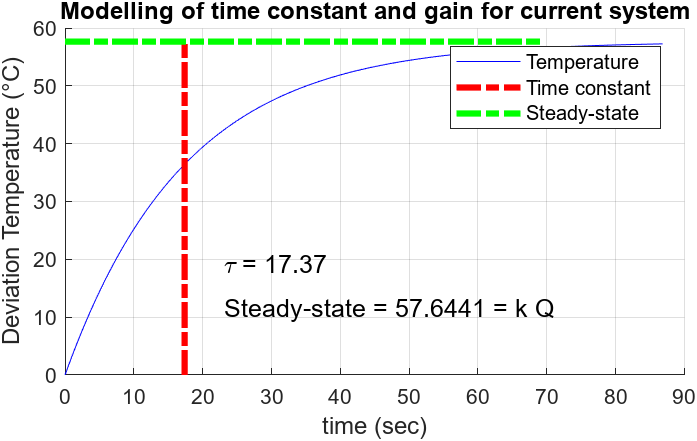

## 4. Supporting MATLAB code

Note that for convenience and simplicity the code in sections 4.1-4.3 assumes that the tank is always beginning from an initial temperature of T(0)=0. Of course, in practice that is not true and thus one may need to use deviation variables which are discussed in  section 4.4.

### **4.1 Response to change in steam flow only**

For simplicity one can use Laplace transforms and ***step.m*** to form the generic open-loop model and the corresponding step response.


$$\begin{array}{l}
\frac{V}{F}\frac{\mathrm{dT}}{\mathrm{dt}}+T=T_{\mathrm{in}} +\frac{\lambda }{\rho {\mathrm{FC}}_p }Q\;\;\Rightarrow \;T\left(s\right)=G_1 \left(s\right)T_{\mathrm{in}} \left(s\right)+G_2 \left(s\right)Q\left(s\right)\\
G_1 \left(s\right)=\frac{1}{\tau s+1};{\;\;G}_2 \left(s\right)=\frac{k_1 }{\tau s+1};\;\;k_1 =\frac{\lambda }{\rho {\mathrm{FC}}_p };\;\tau =\frac{V}{F}
\end{array}$$


% Model parameters
V = 3; Tin=10; rho=1000; lambda=2300000; 
Cp=4200; F=0.4; Q=5;

% Form transfer function models
k1= lambda/(rho*Cp*F);
tau= V/F; %Time constant
G1 = tf(1,[tau,1]);
G2 = tf(k1,[tau,1]);
p1=G1*Tin+G2*Q

% Form and plot step response
time=linspace(0,5*tau,200);
[y,t]=step(p1,time);
plot(t,y,'linewidth',2)
title(['Step response with Q = ',num2str(Q),', Tin = ',num2str(Tin),', T(0) = 0',', F = ',num2str(F)])
xlabel('Seconds')
ylabel('Temperature (°C)')


### **4.2 Response to changes in the inlet flow **

In the presence of an inlet flow disturbance, the amount of inlet flow affects both the time constant as well as the steady state value of the system. Here we assume  that the inlet flow changes as follows:


$$F\;\longrightarrow F+F_d$$


Consequently, the models highlighted in section 4.1 change as follows:


$$G_1 \left(s\right)=\frac{1}{\tau s+1};{\;\;G}_2 \left(s\right)=\frac{k_1 }{\tau s+1};\;\;k_1 =\frac{\lambda }{\rho {\left(F+F_d \right)C}_p };\;\tau =\frac{V}{F+F_d }$$


**Note**: The code will prevent the overall flow becoming negative or zero.

disp('%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%')
disp('Section 4.2 below')
% Model parameters as in section 4.1
FlowinDist=0.1; TinDist=0;
% Flow parameters
%Tin_total= Tin+Tin*(TinDist/100)
F_total= (F+FlowinDist);
k1= lambda/(rho*Cp*F_total);
tau= V/(F_total); %Time constant

p1 =
 
    126.3 s + 16.85
  --------------------
  56.25 s^2 + 15 s + 1
 
Continuous-time transfer function.
Model Properties


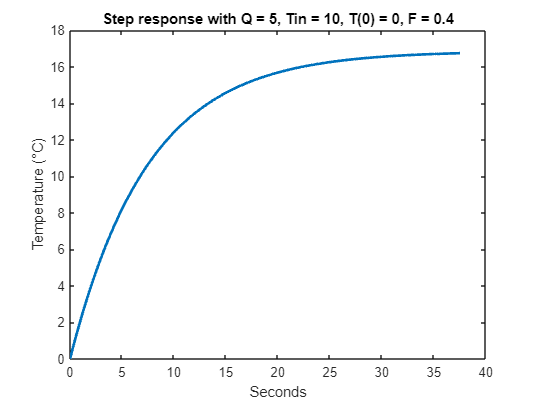


% transfer function models
G1d = tf(1,[tau,1]);
G2d = tf(k1,[tau,1]);
p1d = G1d*Tin+G2d*Q;

% Create and plot response
[yd,td]=step(p1d,time);

plot(t,y,'b',td,yd,'g')
disp(['Q = ',num2str(Q),', Tin = ',num2str(Tin),', T(0) = 0',', F = ',num2str(F)])
title(['Step response with disturbance flow \delta F = ',num2str(FlowinDist)])
legend('Original flow','With disturbance flow','Location','SouthEast')
ylabel('Temperature (°C)')

### **4.3 Response to changes in the  inlet temperature**

In the presence of a change in inlet temperature, the main impact is on the steady-state,  not the dynamics.


$$T_{\mathrm{in}} \;\longrightarrow T_{\mathrm{in}} +T_{\mathrm{in},d}$$


Consequently, the models highlighted in section 4.1 change as follows:


$$\begin{array}{l}
\;T\left(s\right)=G_1 \left(s\right)\left(T_{\mathrm{in}} \left(s\right)+T_{\mathrm{in},d} \left(s\right)\right)+G_2 \left(s\right)Q\left(s\right)\\

\end{array}$$


disp('%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp('Section 4.3 below')

Section 4.2 below


% Model parameters as in section 4.1
TinDist=3;
% Flow parameters
Tin_total= Tin+TinDist;
k1= lambda/(rho*Cp*F);
tau= V/(F); %Time constant

% transfer function models
G1t = tf(1,[tau,1]);
G2t = tf(k1,[tau,1]);
p1t=G1t*Tin_total+G2t*Q;

% Create and plot response
[yt,tt]=step(p1t,time);
disp(['Q = ',num2str(Q),', Tin = ',num2str(Tin),', T(0) = 0',', F = ',num2str(F)])
plot(t,y,'b',tt,yt,'r')
title(['Step response with inlet temperature disturbance \delta T_{in} = ',num2str(TinDist)])

Q = 5, Tin = 10, T(0) = 0, F = 0.4


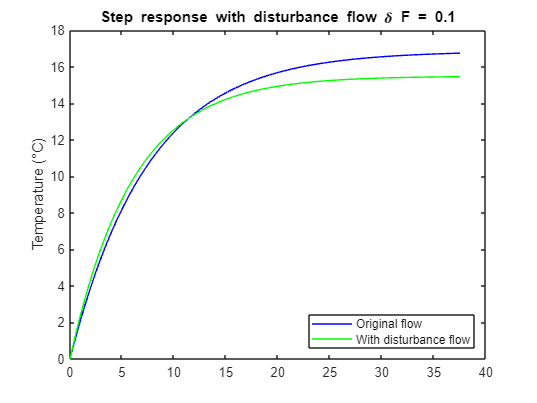

legend('Original T_{in}','With disturbed T_{in}','Location','SouthEast')
ylabel('Temperature (°C)')


### **4.4 Taking account of the initial temperature in the tank**

In reality the tank will have an initial temperature which is not zero.  The easiest way to handle this could be with deviation variables, so define the inlet flow temperature as relative to the initial tank temperature.


$$T_o =T\left(0\right);{T_{\mathrm{in}} }^{\prime } =T_{\mathrm{in}} -T_o$$


With this small change, all the calculations in sections 4.1-4.3 will be correct as long as we remember that temperature is now in the deviation scale.  We move back to real temperature by adding the shift *T(0)*. Note that $T_{\mathrm{in},d}$ is already a deviation from $T_{\mathrm{in}}$ so does not need changing.

Consequently, the models in the sections above are in effect for:


$$\;T^{\prime } \left(s\right)=G_1 \left(s\right)\left({T_{\mathrm{in}} }^{\prime } \left(s\right)+T_{\mathrm{in},d} \left(s\right)\right)+G_2 \left(s\right)Q\left(s\right)$$


Then $T\left(s\right)=T^{\prime } \left(s\right)+T_o \left(s\right)$.

disp('%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp('Section 4.4 below - allowing for non-zero initial temperature')

Section 4.3 below


% Model parameters and models as in above sections
T0=4; Tindash = Tin-T0;

p1=G1*Tindash+G2*Q;
p1d=G1d*Tindash+G2d*Q;
p1t=G1t*(Tindash+TinDist)+G2t*Q;

% Create and plot responses
[y,t]=step(p1,time);
[yd,td]=step(p1d,time);
[yt,tt]=step(p1t,time);
disp(['Q = ',num2str(Q),', Tin = ',num2str(Tin),', T(0) = 0',', F = ',num2str(F)])
disp(['\delta F = ',num2str(FlowinDist), ', \delta T_{in} = ',num2str(TinDist)])
plot(t,y+T0,'b',td,yd+T0,'g',tt,yt+T0,'r')
title(['Step responses with non-zero initial condition'])

Q = 5, Tin = 10, T(0) = 0, F = 0.4


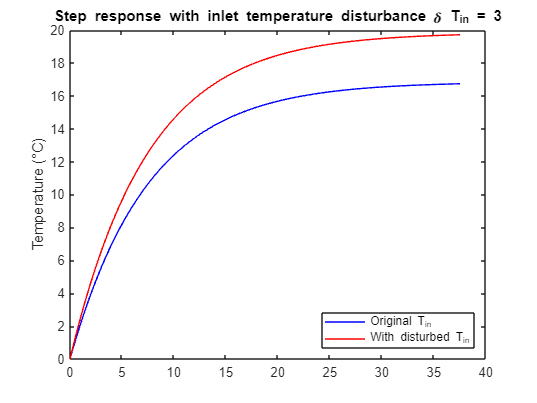

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Section 4.4 below - allowing for non-zero initial temperature


Q = 5, Tin = 10, T(0) = 0, F = 0.4


\delta F = 0.1, \delta T_{in} = 3


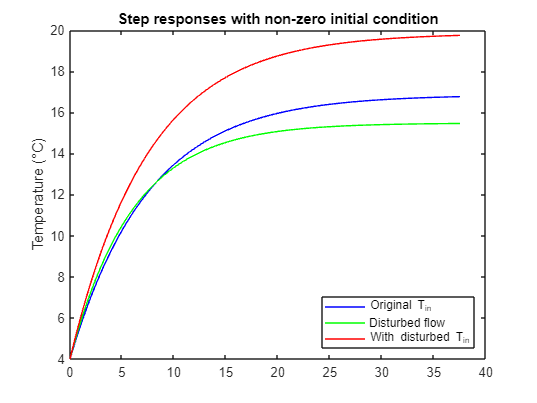

legend('Original T_{in}','Disturbed flow','With disturbed T_{in}','Location','SouthEast')
ylabel('Temperature (°C)')

## **5. **Interface and user interaction of the app file

The user can change 6 parameters (Inlet temperature, volume, flow-in, steam mass flow rate disturbance inlet flow and disturbance inlet temperature) and thus investigage easily the impact of changes. The parameters can only take a finite number of discrete values, as on the sliders, to avoid excessive decimal places.

- The top figure shows the heat exchanger and inlet/outlet pipes. The dimensions of these change to reflect volume and flow rate. The colour changes to reflect the temperature: blue for cold and pink/red for hot. The heater is represented by the bright red line which changes thickness to reflect the choice of ***Q***. The minimum value is 0.01 to prevent failure of the bottom left figure.

- The bottom right figure overlays all recent choices so the comparison is easy to view.

- The bottom left figure shows the time constant and gain analysis for the current choices (ignoring the $T_{\mathrm{in}}$ terms as discussed above).

- For convenience to avoid additional inputs, the initial temperature in the tank is always taken as *T(0)=10*.

The app will overlay all recent responses so the comparison is clear - simulations run for about 5 time constants, so are parameter choice dependent. The legend keeps track of key parameter choices not obvious from the graph. To refresh and begin again, use the refresh button.

You can disable the animation to see quicker responses using the 'animation on/off' button.